10.41

close all
clear
clc

mot.k = 5.2;
mot.T = 0.03;
Ts = 0.01;

s = tf('s');

Pc = mot.k / (s * (mot.T * s + 1));
Pd = c2d(Pc, Ts, "zoh");

z = tf('z', Ts);
s = (z - 1) / Ts;
tau = 0.284;
alpha = 0.031;
Cd = minreal((tau * s + 1) / (s * (alpha * tau * s + 1)), 1e-6);

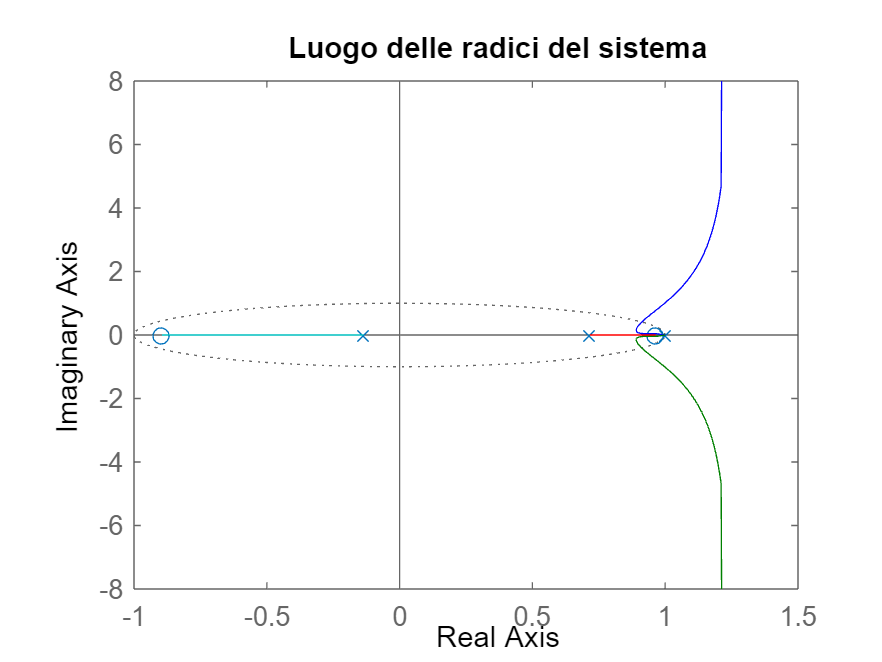

L = minreal(Pd * Cd, 1e-6);
close all
figure(1)
rlocus(L)
title("Luogo delle radici del sistema")

kcrit = margin(L)

kcrit = 46.8087

Per 0 <= k < kcrit il sistema è BIBO stabile.

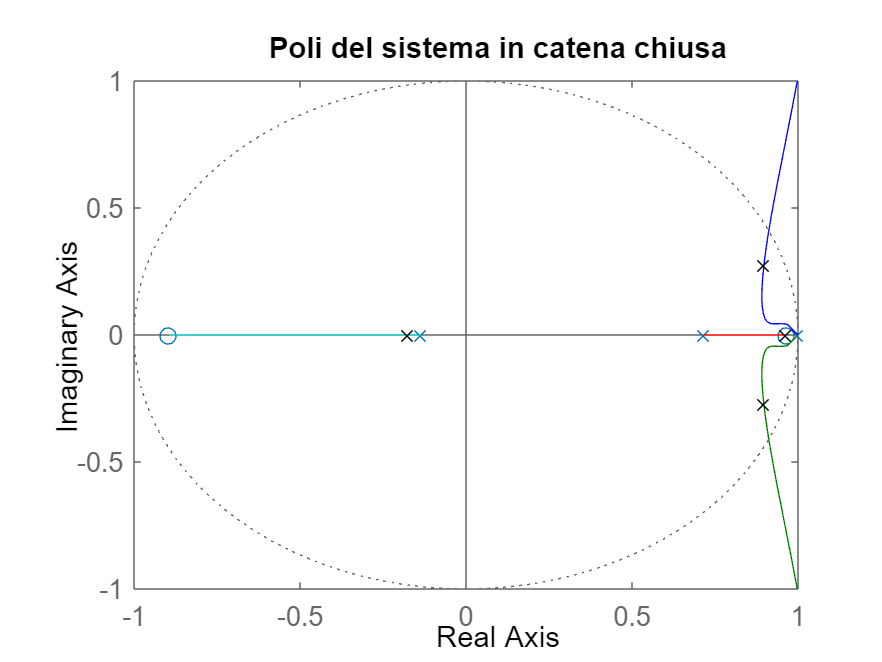

k = kcrit / 2;
L1 = k * L;
T = minreal(feedback(L1, 1), 1e-6);
poles = pole(T);
close all
figure(2)
hold on
rlocus(L1)
plot(real(poles), imag(poles), "kx")
xlim([-1 1])
ylim([-1 1])
title("Poli del sistema in catena chiusa")

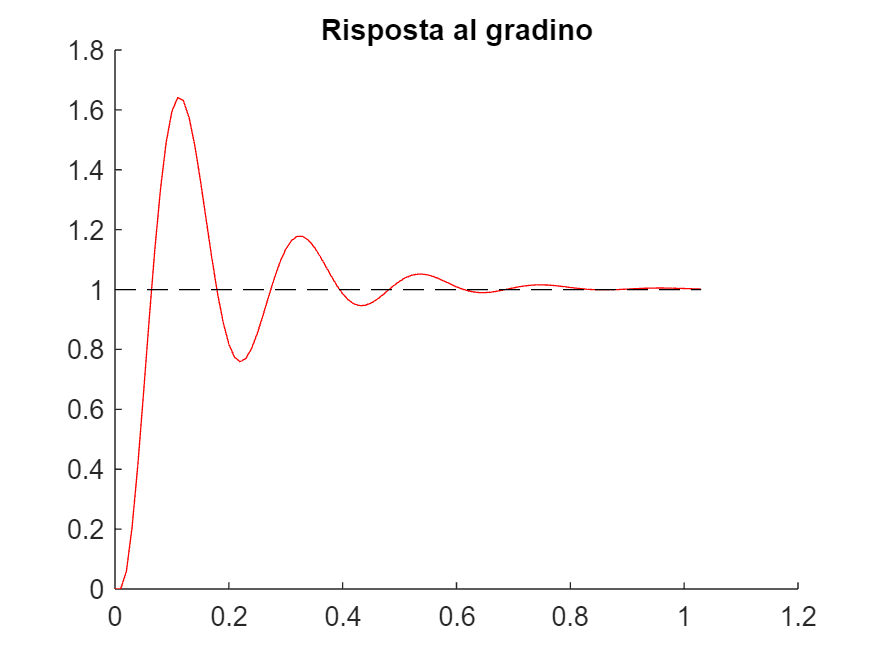

[y, t] = step(T);
close all
figure(3)
hold on
plot(t, y, "r")
plot([t(1), t(end)], [1, 1], "k--")
title("Risposta al gradino")

infos = stepinfo(T, "SettlingTimeThreshold", 0.05)

infos = struct with fields:
         RiseTime: 0.0400
    TransientTime: 0.5500
     SettlingTime: 0.5500
      SettlingMin: 0.7589
      SettlingMax: 1.6405
        Overshoot: 64.0467
       Undershoot: 0
             Peak: 1.6405
         PeakTime: 0.1100


10.49